# Tutorial 1: Basic Functions

## Introduction

Our analytical model involves two main functions: RCMUTModel(), and edrc(). The RCMUTModel() function does all the calculations, while edrc() is a more convenient interface to input parameters in.The simplest way to use this model is to

- Define a structure with your device and analysis parameters

- Pass that structure into the edrc() function. The function will return the simulation results

- Plot/analyze the results.

For most use cases, the only things you will need to learn are:

- What parameters to input

- How to interpret the output results.

### Function Inputs

To see a list of all parameters, their default values, and what they do, you can check documentation for the function RCMUTModel(). 

%Add the path of the modeling code:
filePath = matlab.desktop.editor.getActiveFilename; %get active file location
TutorialsFolder = fileparts(filePath); ProjectFolder = fullfile(TutorialsFolder,'..');
CodePath = fullfile(ProjectFolder,"Code/");addpath(genpath(CodePath))

doc RCMUTModel

However, a faster method is to simply run the edrc function with no inputs and view the parameters.

temp = edrc(); temp.BasicParams

ans = struct with fields:
                               a: 6.0000e-05
                               b: 0.0015
                               h: 5.0000e-06
                              d0: 5.0000e-07
                              di: 3.6000e-07
                            epsr: 3.9000
                               E: 1.4800e+11
                             rho: 2329
                               p: 1.0047e+05
                         h_metal: 2.5000e-07
                       rho_metal: 19300
                         E_metal: 7.6000e+10
                           Water: 0
            UseCustomFluidMedium: 0
                      DeviceType: 'CD'
                  calcHysteresis: 0
           BiasByCollapsePercent: 1
                 collapsePercent: [0.2000 0.5000 0.8000 0.9500]
                            fmin: 100000
                            fmax: 5000000
                           fstep: 10000
                       fstepFine: 2000
    fineFsweepRangeScalingFactor: 1
        

This generates a structure with the most commonly used parameters, and their default values. You can also evaluate "temp.Params" to see a similar structure of all parameters, however we will restrict ourselves to the basic parameters in this document. 

Every parameter has a default value, so you only need to input the parameters you want to change. All input parameters are in SI units.

### Function Outputs

After simulating your device, the function you used (RCMUTModel() or edrc()) returns a structure containing many results. These include electrostatic results, dynamic model parameters, and frequency response results such as membrane velocity, input impedance, and output pressure. All output values are also in SI units.

 Let's look at some examples to see how they are used.

## Example 1: Electrostatic Analysis

#### Step 0: Ensure the model functions are in MATLAB's path

%Add the path of the modeling code:
filePath = matlab.desktop.editor.getActiveFilename; %get active file location
TutorialsFolder = fileparts(filePath); ProjectFolder = fullfile(TutorialsFolder,'..');
CodePath = fullfile(ProjectFolder,"Code/");addpath(genpath(CodePath))

#### Step 1: Define a structure for our parameters

clear CMUT; CMUT = struct;

We could populate this structure by setting it equal to temp.BasicParams. That would let us take advantage of MATLAB's autocomplete functions and see all the possible parameters. However to demonstrate that you only need to change the parameters you care about, we will not do that in this example.

Now we just input the dimensions and material properties of our desired device:

%device dimensions: 
CMUT.a = 60e-6; %membrane half-width [m]
CMUT.h = 5e-6; %membrane thickness [m]
CMUT.d0 = 480e-9; %cavity vacuum gap [m]
CMUT.b = 1.5e-3; %membrane half-length [m]
CMUT.di = 360e-9; %insulating layer thickness [m]

%material properties:
CMUT.epsr = 3.9; %relative permittivity of dielectric layer
CMUT.E = 148e9; %Young's Modulus of membrane [Pa]
CMUT.rho = 2329; %Density of membrane [kg/m^3]

Note that the default parameters assume a metal layer of 250 nm-thick gold. Let's remove that for this simulation

%Metal electrode layer:
CMUT.h_metal = 0; %Electrode thickness [m]

#### Step 2: Simulate your parameters with edrc

When all of your device parameters have been input, you can simulate your device.

%Simulates the device with the chosen parameters, returns a structure with the results.
results = edrc(CMUT); 

#### Step 3: Plot/analyze the results

Let us begin by plotting membrane deflection as a function of bias voltage

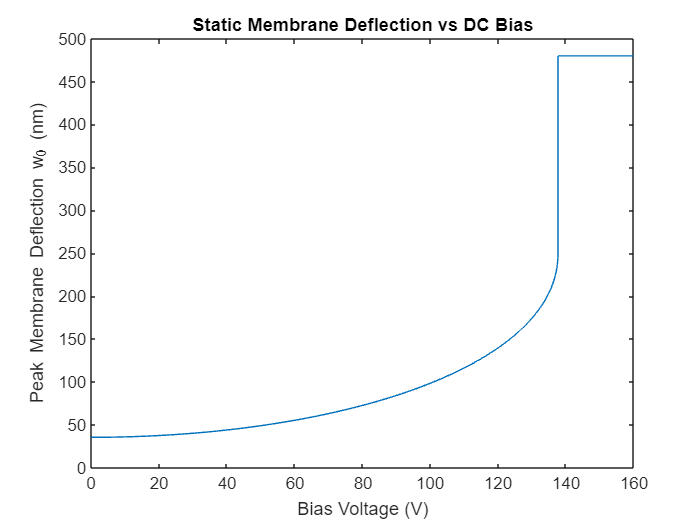

figure
plot(results.VDC,results.w0*1e9)
xlabel('Bias Voltage (V)')
ylabel('Peak Membrane Deflection w_0 (nm)')
title('Static Membrane Deflection vs DC Bias')

We can see the inital deflection from atmospheric pressure at 0V, and that membrane deflection increases as more DC voltage is applied, until the membrane finally collapses.

Some other useful quantities here include:

%Collapse voltage:
Vc = results.Vc

Vc = 137.6439

%Initial Deflection: (in m)
InitialDeflection = results.w0(1)

InitialDeflection = 3.5191e-08

In addition to the membrane deflection, you can also plot the capacitance. 

Capacitance as a function of bias voltage:

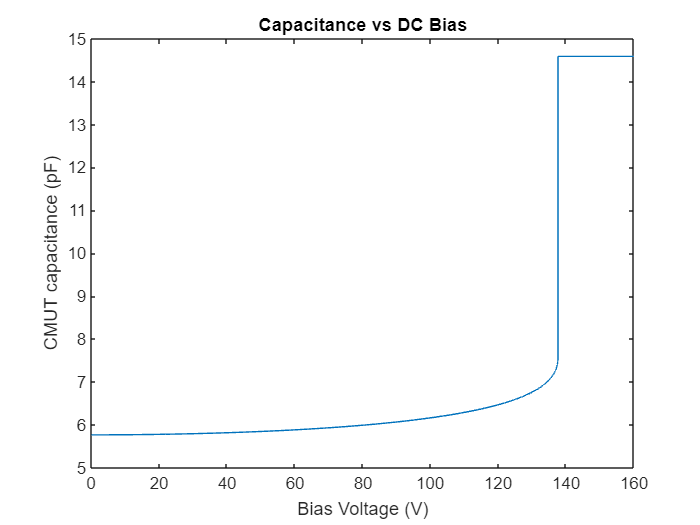

figure
plot(results.VDC,results.C0 *1e12)
xlabel('Bias Voltage (V)')
ylabel('CMUT capacitance (pF)')
title('Capacitance vs DC Bias')

Capacitance as a function of membrane deflection:

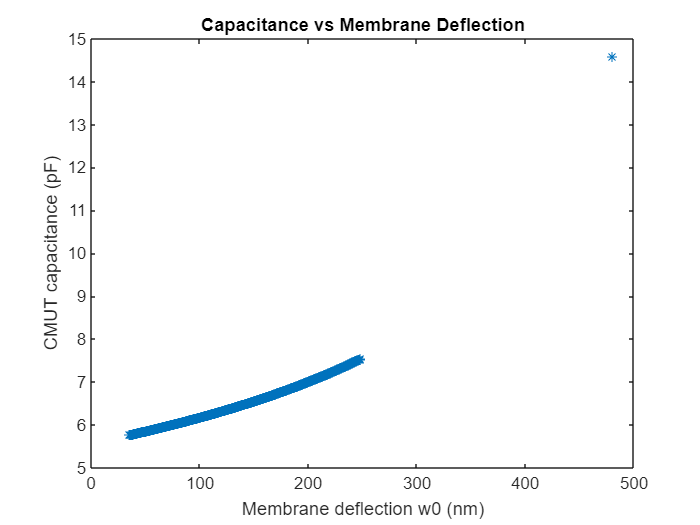

figure
plot(results.w0*1e9,results.C0 *1e12,'*')
xlabel('Membrane deflection w0 (nm)')
ylabel('CMUT capacitance (pF)')
title('Capacitance vs Membrane Deflection')

Also note that we simulated > 2000 bias voltages between 0 and the collapse voltage, and that it didn't take very long. This increment can be controlled with the parameter "w0_increment". However, it is not recommended to increase this parameter as that will impact the accuracy of the capacitance derivatives, and thus your overall simulations.

length(results.w0)

ans = 2236

## Example 2: Dynamic Analysis

This code performs both static and dynamic analysis in the same execution. In the above example, we also obtained dynamic results. Let's analyze those results, then learn how to change analysis parameters for more dynamic simulations.

### 2.1: Dynamic model basics

The default settings simulate our device at 4 different operating points:

- Operating at 20% of the collapse voltage

- Operating at 50% of the collapse voltage

- Operating at 80% of the collapse voltage

- Operating at 95% of the collapse voltage

Of course this requires the static analysis to be completed first. We use percentages of the collapse voltage rather than hard-coded voltage values because our dynamic model is only valid for pre-collapse operation. Thus, we do not want to get errors from a hard-coded voltage being above the collapse voltage. 

The dynamic model works by determining the capacitance and deflection at each operating voltage, then calculating the relevant dynamic model parameters as described in our manuscript. Then it 

The dynamic model works in a few steps:

- Determine capacitance and deflection at each operating voltage based on static analysis

- Calculate relevant circuit model parameters as described in our manuscript

- Determine approximate resonance frequency, and generate array of input frequencies based on user inputs. In air, this frequency array will have extra points near the approximate resonance frequency, as air operation usually involves high Q factors.

- Calculate the radiation impedance of the membrane interactions with the fluid medium at every input frequency

- Analyze the circuit at each input frequency, extract velocity, force, and input impedance parameters

- Repeat 2-5 for each operating voltage.

- Extract some key frequencies and return all results.

By default, the code assumes an air fluid medium. However, it is easy to change this to a water medium, or define a custom fluid medium with its own density and speed of sound.

### 2.2: Analyze dynamic model output

#### Operating points

Let's first look at the bias voltage, membrane deflection, and capacitance at each operating point.

OperatingVoltages = results.Vop

OperatingVoltages =    27.5288
   68.8220
  110.1151
  130.7617


OperatingDeflection = results.wop

OperatingDeflection = 1.0e-06 *

    0.0392
    0.0619
    0.1163
    0.1778


OperatingCapacitance = results.Cop

OperatingCapacitance = 1.0e-11 *

    0.5784
    0.5920
    0.6286
    0.6789


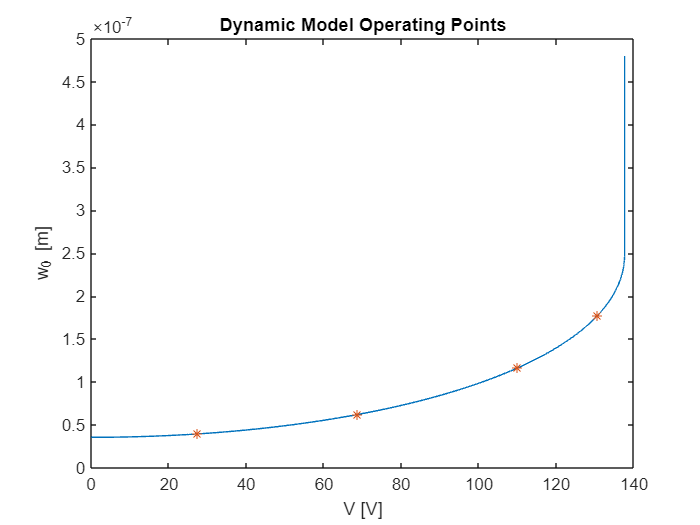

%plot compared to overall electrostatic V vs w0 plot:
plot(results.VINC,results.w0INC);xlabel('V [V]');ylabel('w_0 [m]')
hold on; plot(OperatingVoltages,OperatingDeflection,'*');
title('Dynamic Model Operating Points')

#### Circuit Model Parameters

Now let's look at the circuit model parameters, which are generated in case you want to do subsequent analysis in dedicated circuit simulation software.

phi = results.phi;%electromechanical transformer ratio
Ceq = results.MechCap %effective compliance (capacitance in mechancial domain)

Ceq = 1.0e-05 *

    0.1845
    0.1982
    0.2502
    0.4050


Lm = results.MechL %effective mass (inductance in mechanical domain)

Lm = 1.0e-08 *

    0.1703
    0.1703
    0.1703
    0.1703


%c0 is equal to Cop / "OperatingCapacitance" defined above.

The radiation impedance is a frequency-dependent quantity, hence it is a vector stored in a cell array for each operating point. The length of the frequency vector at each bias may be different, thus cell arrays are the most convenient storage.

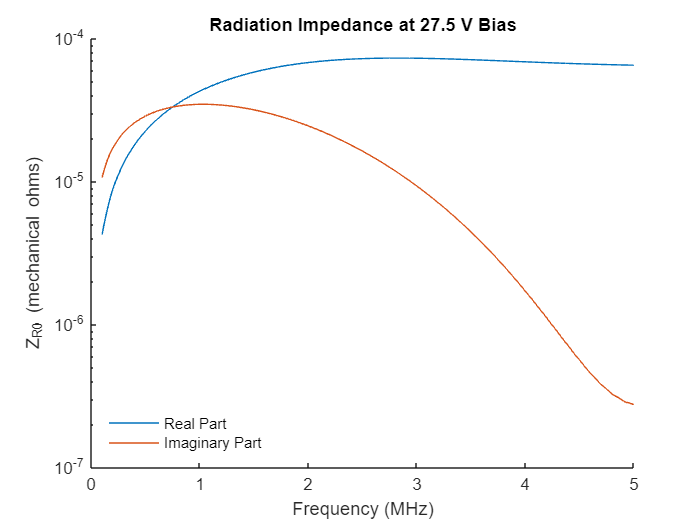

OpPoint = 1; %you can change this between 1-4 to see each different operating point
%here the radiation impedance is the same at each bias voltage, so changing it makes no difference
figure;hold on
title(sprintf('Radiation Impedance at %.1f V Bias',results.Vop(OpPoint)))
plot(results.f{OpPoint}/1e6,real(results.ZR0{OpPoint})); %real portion
xlabel('Frequency (MHz)');ylabel('Z_R_0 (mechanical ohms)');hold on;
plot(results.f{OpPoint}/1e6,imag(results.ZR0{OpPoint})); %imaginary portion
set(gca, 'YScale', 'log')
legend('Real Part','Imaginary Part');legend('location','southwest');legend('boxoff')

#### Frequency Response Results

Other dynamic quantities can be viewed and plotted in the same way. Here we will view the input impedance of the CMUT.

figure
plot(results.f{1}/1e6,abs(results.Zin{1})); %Impedance magnitude at 20% Vc
xlabel('Frequency (MHz)');ylabel('| Z_i_n | (ohms)');hold on;
plot(results.f{2}/1e6,abs(results.Zin{2})); %Impedance magnitude at 50% Vc
set(gca, 'YScale', 'log')
legend('20% Vc Bias','50% Vc Bias');legend('location','southwest');legend('boxoff')
title('Input Impedance (Air Operation)')

Here we can clearly see the resonance frequency (impedance magnitude local minimum), and antiresonance frequency (impedance magnitude local maximum). Our model automatically determines these frequencies at each operating point.

resonanceFreqs = results.fr %resonance frequencies

resonanceFreqs =      2838000     2738000     2438000     1914000


antiresFreqs = results.fa %antiresonance frequencies

antiresFreqs =      2850000     2820000     2736000     2610000


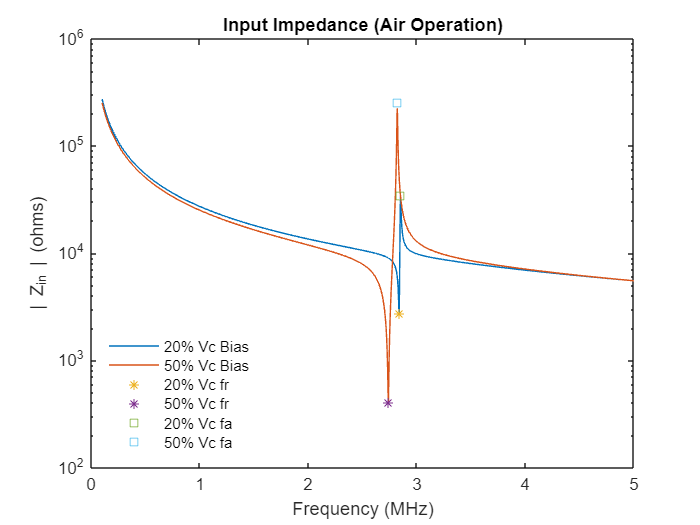

%show these frequencies on the plot:
%Resonance frequencies:
plot(resonanceFreqs(1)/1e6,min(abs(results.Zin{1})),'*') %resonance at 20% Vc.
plot(resonanceFreqs(2)/1e6,min(abs(results.Zin{2})),'*') %resonance at 50% Vc.
%evaluating a global minimum to find the corresponding impedance will not work in every case.
%Our model uses a more sophisticated approach.
%Antiresonance frequencies:
%for the 20% Vc point, fa is not at the global maximum,
%so when evaluating a maximum we only consider the second half of the array
plot(antiresFreqs(1)/1e6,max(abs(results.Zin{1}(floor(end/2):end))),'sq') %antiresonance at 20% Vc.
plot(antiresFreqs(2)/1e6,max(abs(results.Zin{2})),'sq') %antiresonance at 50% Vc.
legend('20% Vc Bias','50% Vc Bias','20% Vc fr','50% Vc fr','20% Vc fa','50% Vc fa');

Many other quantities, such as force, pressure, deflection, and velocity can also be plotted in the same manner. See our documentation or the results structure for a list of frequency dependent outputs.

### 2.3: Immersion & Analysis Parameters

When evaluating the frequency response, the analysis options you are most likely to care about are the frequency sweep, the fluid medium, and the operating point. These parameters are simply added to the input structure the same way as device dimensions.

CMUT = results.BasicParams; %load the parameters of the previous simulation

#### Defining Fluid Medium

To toggle between air and water fluid media, you can simply change the "Water" parameter.

CMUT.Water = 1; %Toggle between air or water. 1 = Water, 0 = air. Default - 0 (air).

To define a custom fluid medium, you can enable the "UseCustomFluidMedium" parameter, which enables you to define a custom speed of sound and density. IMPORTANT: This parameter over-rules whatever is pre-defined with the "Water" parameter.

%Soybean oil medium:
CMUT.UseCustomFluidMedium = 1; %1 = enabled, 0 = disabled. Default - Disabled.
% FluidDensity and FluidSpeedOfSound do not do anything unless UseCustomFluidMedium = 1.
CMUT.FluidDensity = 920.29; %Custom fluid medium density [kg/m^3]
CMUT.FluidSpeedOfSound = 1484.1; %Custom fluid medium speed of sound [m/s]

#### Defining Frequency Sweep

As mentioned above, the frequency sweep behaves differently depending on whether the device is in air or water. This is controlled by the water parameter. Hence, it is recommended to enable "CMUT.Water = 1" even when using a custom fluid medium.

The bounds of the frequency sweep are defined by the following parameters:

CMUT.fmin = 100e3; %Minimum Frequency [Hz]
CMUT.fmax = 5e6; %Maximum Frequency [Hz]
CMUT.fstep = 10e3; %Frequency step size [Hz]
CMUT.fstepFine = 2e3; %Fine frequency step size [Hz] (air only).

This will define a frequency array from fmin to fmax in steps of fstep. In the case of air (CMUT.Water = 0), points near the predicted resonance frequency will have a finer frequency step size determined by CMUT.fstepFine.

It is also possible to define your own custom frequency sweep using

CMUT.UseDefaultFrequencySweep = 0; % 1 = enable default sweep, 0 = use custom sweep specified by CustomFrequencySweepRange
CMUT.CustomFrequencySweepRange = 100e3:5e3:5e6; %Custom Frequency Sweep. Enabled with UseDefaultFrequencySweep = 0

#### Custom Operating Points

To change the operating voltages, there are 2 main approaches. One is to specify the operating voltages as fractions of the collapse voltage.

CMUT.collapsePercent = [0.2 0.5 0.8 0.95]; %Specify bias voltage as fraction of collapse voltage
%must be greater than 0 and less than 1.

However, as we have already completed a static analysis of this device, and therefore know the collapse voltage, we can also manually specify the bias voltages:

CMUT.BiasByCollapsePercent = 0; %toggles between fraction of the collapse voltage and Manual bias input
% BiasByCollapsePercent = 1 -> uses collapsePercent (default)
% BiasByCollapsePercent = 0 -> uses ManualBiasVoltage
CMUT.ManualBiasVoltage = 20:20:120;%Operating voltage for dynamic model in [V], enabled with BiasByCollapsePercent = 0

The final parameter of interest is the amplitude of the AC driving signal. This is specified with 

CMUT.VAC = 1; %Amplitude of driving sinusoidal signal [V]

#### Simulation & Processing Results

As with before, we only need to pass the CMUT structure into edrc() then process the results. The frequency range defined above has 981 points, and we are simulating 6 different bias voltages with that frequency (>5000 total frequency points). Moreover, as we saw above, we are simulating > 2000 points in our electrostatic simulation. One may expect this to take a long time. However, that is usually not the case.

tic
result = edrc(CMUT);
toc

Elapsed time is 0.093194 seconds.


Next, we shall plot the velocity and deflection of the membrane

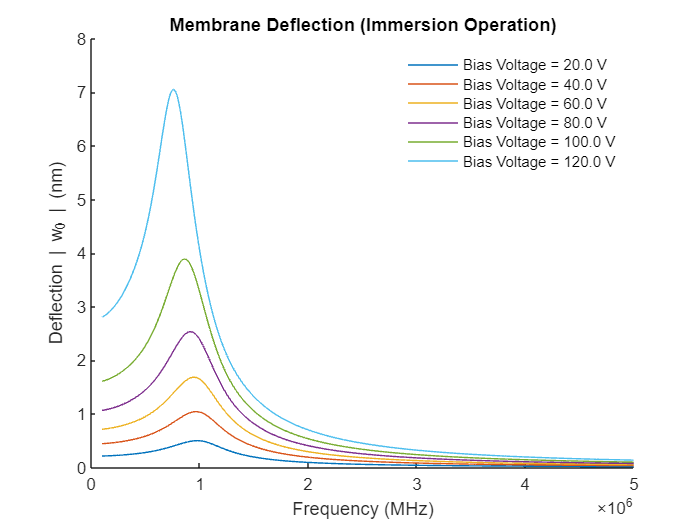

%plot deflection
figure; hold on; clear legendstr
xlabel('Frequency (MHz)');ylabel('Deflection | w_0 | (nm)')
for ii = 1:length(result.Vop)
    plot(result.f{ii},abs(result.w0ac{ii})*1e9)
    legendstr{ii} = sprintf('Bias Voltage = %.1f V',result.Vop(ii));
end
legend(legendstr);legend('boxoff')
title('Membrane Deflection (Immersion Operation)')

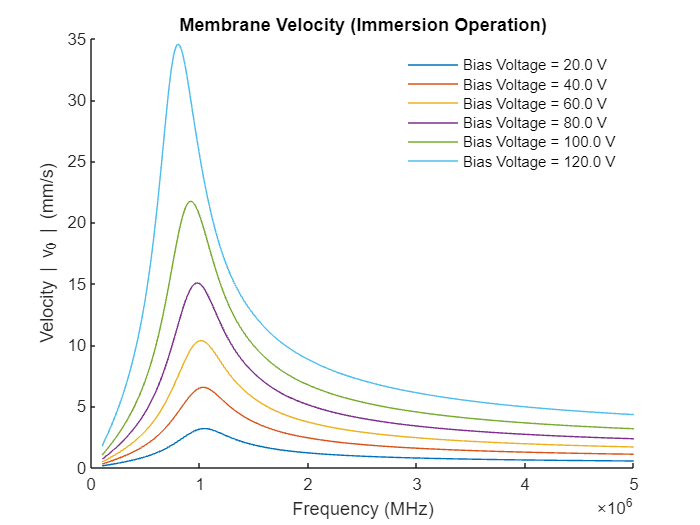


%plot velocity 
figure; hold on; clear legendstr
xlabel('Frequency (MHz)');ylabel('Velocity | v_0 | (mm/s)')
for ii = 1:length(result.Vop)
    plot(result.f{ii},abs(result.v0{ii})*1e3)
    legendstr{ii} = sprintf('Bias Voltage = %.1f V',result.Vop(ii));
end
legend(legendstr);legend('boxoff')
title('Membrane Velocity (Immersion Operation)')

As discussed in our manuscript, lumped force and velocity can be expressed in terms of the peak, average, or RMS average velocity. Force, Pressure, and Velocity corresponding to each are all calculated by our model. However, pressure is usually most accurate when using the RMS average quantities (as discussed in our manuscript).

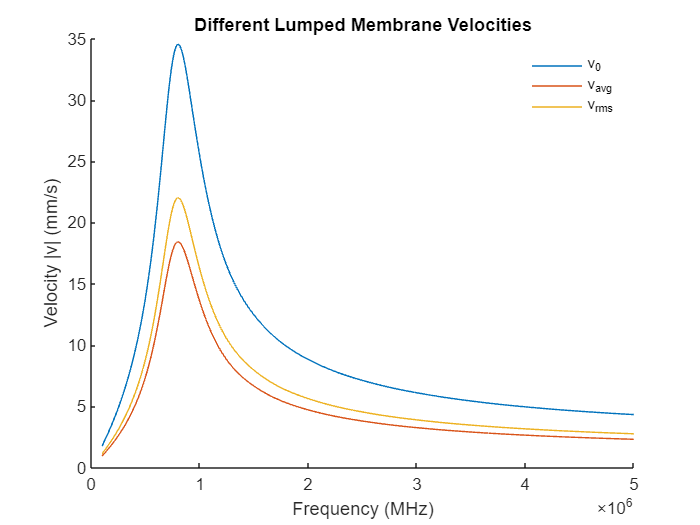

%plot velocity 
figure; hold on;
xlabel('Frequency (MHz)');ylabel('Velocity |v| (mm/s)')
plot(result.f{ii},abs(result.v0{ii})*1e3) %Peak velocity
plot(result.f{ii},abs(result.vAvg{ii})*1e3) %Average velocity
plot(result.f{ii},abs(result.vRMS{ii})*1e3) %RMS average velocity
legend('v_0','v_a_v_g','v_r_m_s');legend('boxoff')
title('Different Lumped Membrane Velocities')

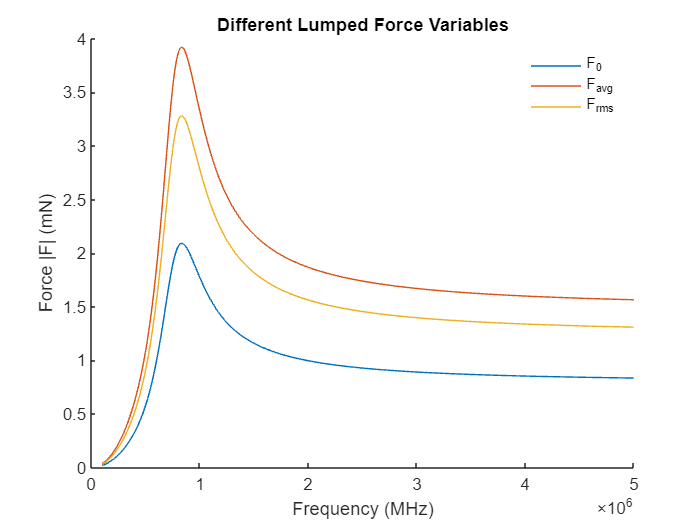

%plot Force 
figure; hold on;
xlabel('Frequency (MHz)');ylabel('Force |F| (mN)')
plot(result.f{ii},abs(result.F0{ii})*1e3) %Peak Lumped Force
plot(result.f{ii},abs(result.FAvg{ii})*1e3) %Average Lumped Force
plot(result.f{ii},abs(result.FRMS{ii})*1e3) %RMS average Lumped Force
legend('F_0','F_a_v_g','F_r_m_s');legend('boxoff')
title('Different Lumped Force Variables')

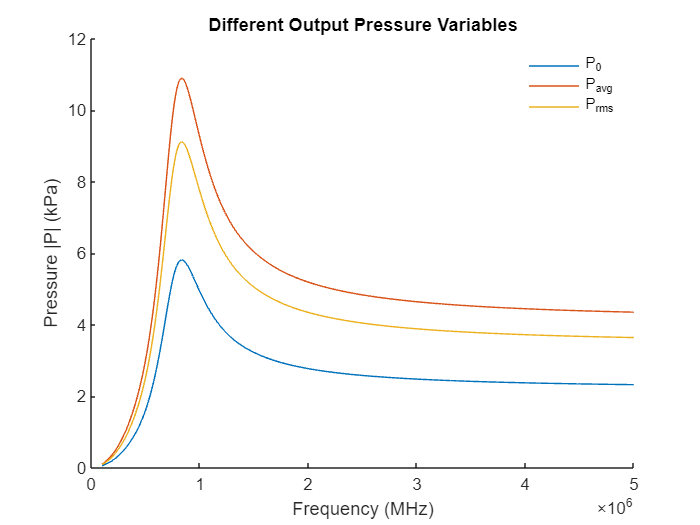

%plot Pressure 
figure; hold on;
xlabel('Frequency (MHz)');ylabel('Pressure |P| (kPa)')
plot(result.f{ii},abs(result.P0{ii})/1e3) %Peak Lumped Pressure
plot(result.f{ii},abs(result.PAvg{ii})/1e3) %Average Lumped Pressure
plot(result.f{ii},abs(result.PRMS{ii})/1e3) %RMS Average Lumped Pressure
legend('P_0','P_a_v_g','P_r_m_s');legend('boxoff')
title('Different Output Pressure Variables')

%note: PRMS can also be obtained with result.Pout or result.P

Also note that power/energy is conserved between each approach.

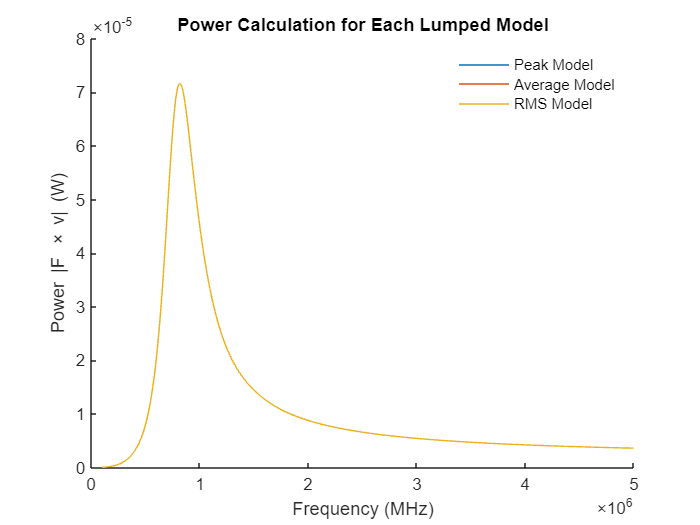

%Plot Power:
figure; hold on;
xlabel('Frequency (MHz)');ylabel('Power |F \times v| (W)')
plot(result.f{ii},abs(result.F0{ii}.*result.v0{ii})) %Power using peak velocity model
plot(result.f{ii},abs(result.FAvg{ii}.*result.vAvg{ii})) %Power using average velocity model
plot(result.f{ii},abs(result.FRMS{ii}.*result.vRMS{ii})) %Power using RMS average velocity model
legend('Peak Model','Average Model','RMS Model');legend('boxoff')
%power can also be obtained with result.PowerOut
title('Power Calculation for Each Lumped Model')

This tutorial summarizes the basic functions of this model and should be sufficient for most users. For more information please see our other example scripts and documentation.